## Linear Algebra Concepts

### Rank

The `rank(A)` function calculates the rank of matrix `A`, which represents the dimension of the column space of `A`. The rank tells us how many linearly independent vectors span the column space.

clc; clear all;close all
% Define Matrix
A = [1 1 2; -1 1 0; 2 1 3];
% Compute the Rank
rank(A)

ans = 2

## Vector Transformation

Matrix-vector multiplication can be visualized as a transformation. When you multiply a vector by a matrix, you transform the vector to a new location in the space defined by the matrix.

### Vectors 3D Space 

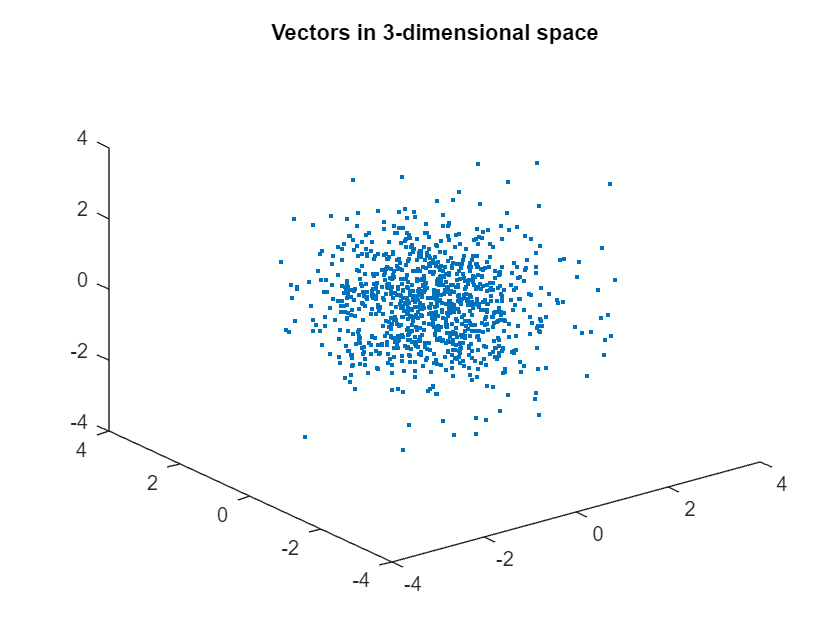

x = randn(3,1000);
figure 
plot3(x(1,:),x(2,:),x(3,:),'.');
title("Vectors in 3-dimensional space");

### Vectors in 3D Space Transformed

The follwing code visually showcases how a set of 3D vectors (from matrix `x`) gets transformed when multiplied by the matrix `A`. The transformation may involve rotations, stretches, or compressions depending on the values in matrix `A`.

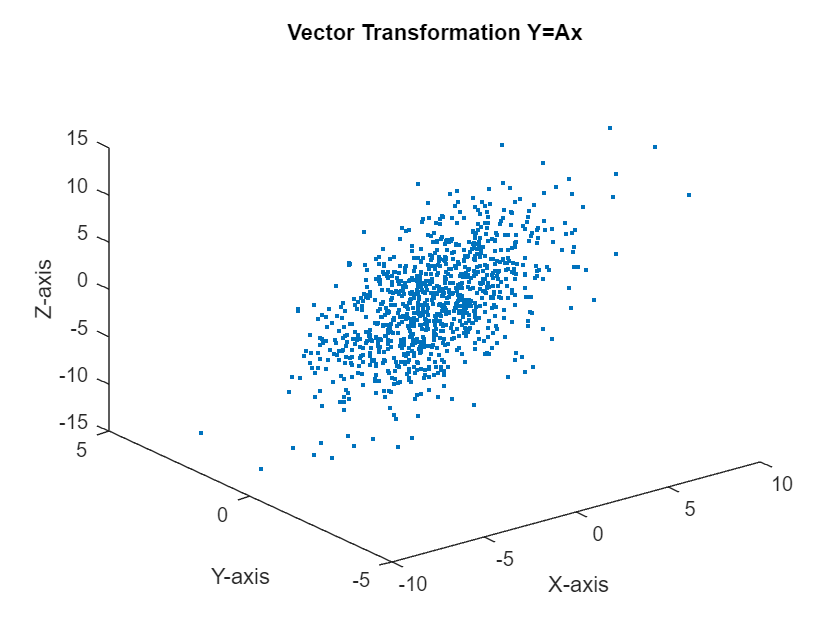

A = [1 1 2; -1 1 0; 2 1 3];

% Transform the set of 3D vectors using matrix A
Y = A*x;

% Create a 3D scatter plot for the transformed vectors
figure; % Open a new figure
plot3(Y(1,:),Y(2,:),Y(3,:),'.')
hold on; 

title("Vector Transformation Y=Ax")
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

### Visualizing Matrix Transformations and Basis Vectors in 3D

The code demonstrates how the matrix *A* acts as a linear transformation on input vectors, transforming them into new positions in the 3D space.

 Additionally, by plotting the column vectors of *A* (a1, a2, and a3) as red lines, it visually highlights these vectors as the basis vectors for the transformation. 

These basis vectors give insight into the "**directions**" and "**scales**" of the transformation applied by *A* in the 3D space. 

The longer the red line in a certain direction, the stronger the influence of that basis vector in that direction.

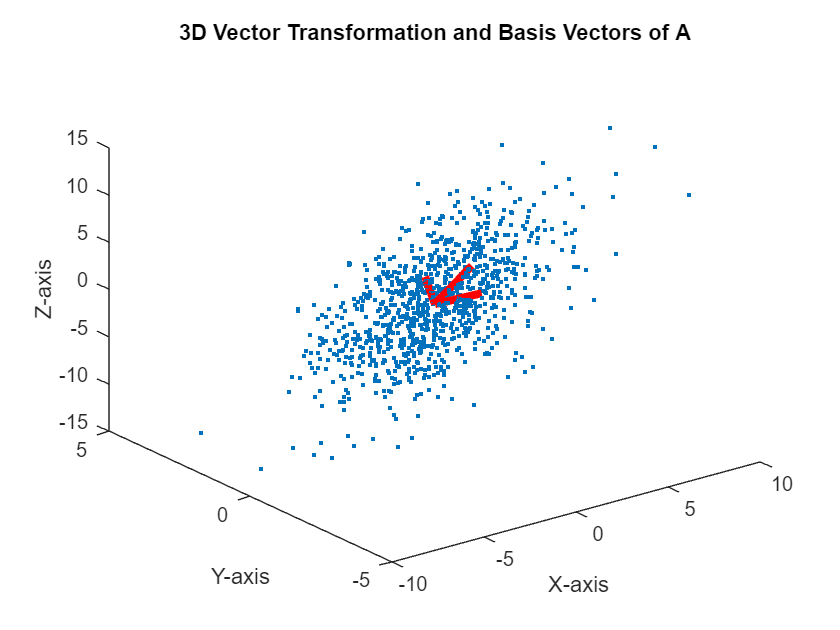

% Transform the set of 3D vectors using matrix A
Y = A*x;

% Create a 3D scatter plot for the transformed vectors
figure; % Open a new figure
plot3(Y(1,:),Y(2,:),Y(3,:),'.')
hold on; 

% Extract the column vectors of matrix A
a1 = A(:, 1); % First column of A
a2 = A(:, 2); % Second column of A
a3 = A(:,3);  % Third column of A

% Visualize the column vectors of A on the same plot
plot3([0 a1(1)], [0 a1(2)], [0 a1(3)], 'r', 'linewidth', 4) % a1 in red
plot3([0 a2(1)], [0 a2(2)], [0 a2(3)], 'r', 'linewidth', 4) % a2 in red
plot3([0 a3(1)], [0 a3(2)], [0 a3(3)], 'r', 'linewidth', 4) % a3 in red

% Add title and labels to the plot
title("3D Vector Transformation and Basis Vectors of A")
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

### Visualizing Column Vectors

In this section we just plot column vectors of a matrix and visualize it 

close all; clear all; clc
% Define matrix A with 3 rows and 4 columns
A = [1 2 3 4; -1 1 -1 1; 0 1 -3 0];
rank(A)

ans = 3

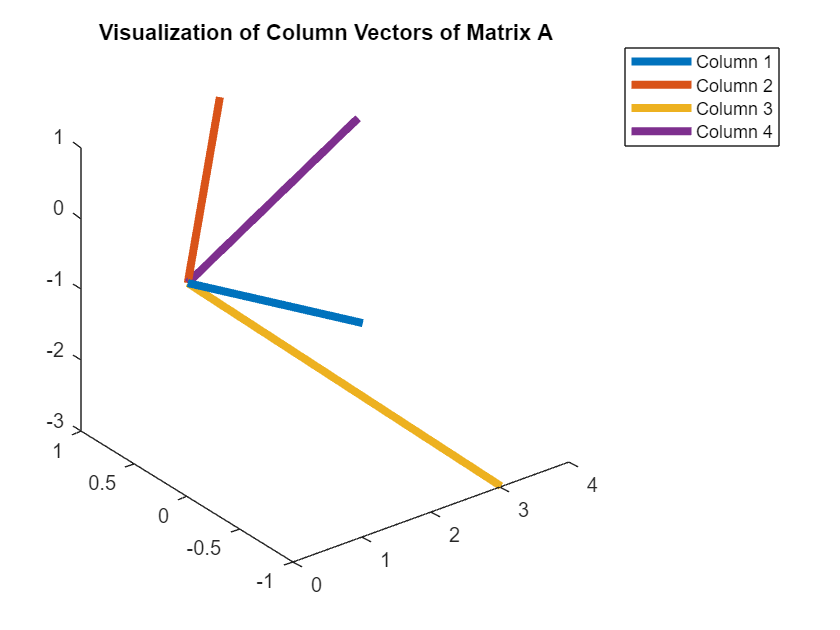


% Create a new figure window for plotting
figure 

% Create an empty cell array to store legend entries
legendEntries = cell(1, 4);

% Loop through each column of matrix A
for i = 1:4
    % Plot the column vector of A as a line segment in 3D space
    % starting from the origin (0,0,0) and ending at the point defined by the column vector
    plot3([0 A(1,i)], [0 A(2,i)], [0 A(3,i)], 'linewidth', 4);
    hold on; % Keep the current plot and add subsequent plots on top
    
    % Add the column index to the legend entries
    legendEntries{i} = ['Column ' num2str(i)];
end

% Add the legend to the plot
legend(legendEntries);

% Set the title for the plot
title('Visualization of Column Vectors of Matrix A');

### Geometric Interpretation of Determinants

For a 2x2 matrix the area of the parallelogram formed by the columns (or rows) of A

For a 3x3 matrix it represents the volume of a parallelopiped formed by the columns (or rows) of A

This concept can be extended to any dimensional matrix

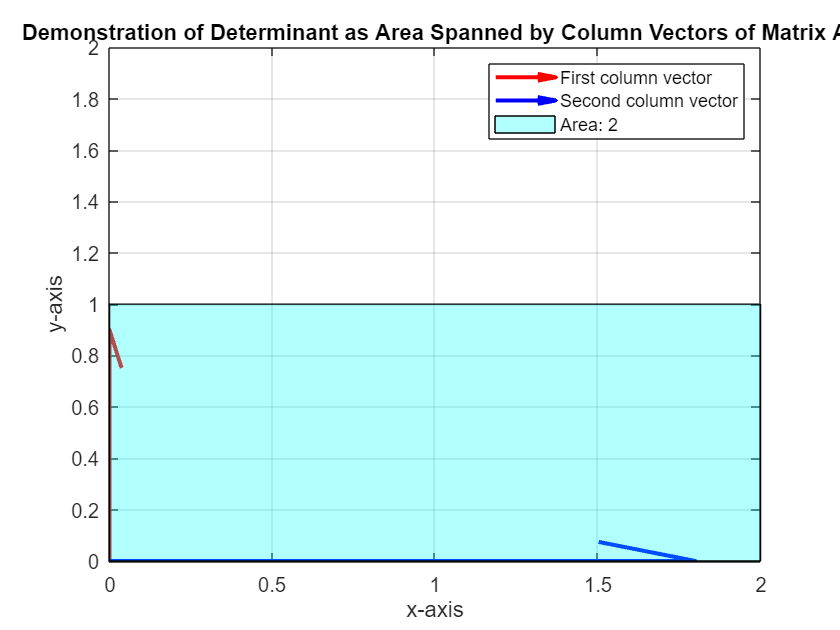

close all; clear all; clc
% Define the matrix A
A = [0 2; 1 0];

% Extract the column vectors
vec1 = A(:,1);
vec2 = A(:,2);

% Create a new figure
figure

% Plot the first vector in red
quiver(0,0,vec1(1),vec1(2),"r","LineWidth",2,"MaxHeadSize",0.5)
hold on 

% Plot the second vector in blue
quiver(0,0,vec2(1),vec2(2),"b","LineWidth",2,"MaxHeadSize",0.5)

% Set the limits of the plot
xlim([0 2]);
ylim([0 2]);

% Turn on the grid
grid on;


% Label the axes
xlabel('x-axis');
ylabel('y-axis');


% Fill the area formed by vec1 and vec2 with a semi-transparent cyan color
fill([0 vec1(1) vec1(1)+vec2(1) vec2(1)],[0 vec1(2) vec1(2)+vec2(2) vec2(2)], 'c', 'FaceAlpha', 0.3)

% Add a legend and title
legend('First column vector', 'Second column vector', ['Area: ', num2str(abs(det(A)))]);
title('Demonstration of Determinant as Area Spanned by Column Vectors of Matrix A');

## Visualizing System Of Equations and their Solutions

In linear algebra, a system of equations can be represented visually using planes in a three dimensional space. 

The following matrix A and the vector b defines our system of equations. Each equation represents a plan in 3D space. 

The way the planes interact will tell provide insight on the solution of the system

- If the planes intersect at a single point, the system has a unique solution

- If they intersect along a line, the system has infinite solutions

- If there are no common intersections among the planes, the system has no solutions

### One Solution

The following is showcasing one solution we can tell as there is only one intersection point of all 3 planes. We can verify this using a variety of methods

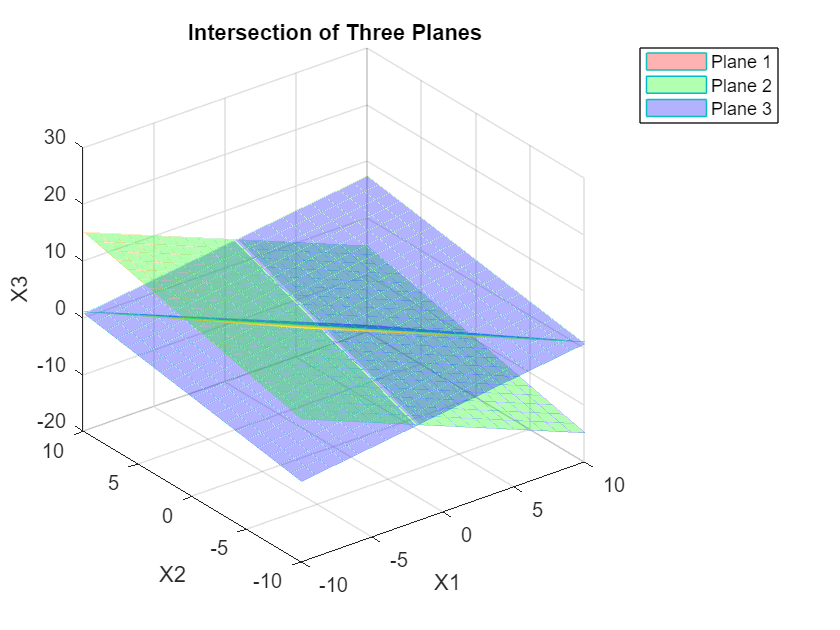

A = [1 1 1; 2 -1 2; -1 -1 3];
b = [1; 0; 2];
[X1, X2] = meshgrid(-10:10);
figure

% Plotting the first plane
X3 = -X1 - X2 + 1;
mesh(X1, X2, X3, 'FaceColor', 'r', 'FaceAlpha', 0.3, 'EdgeAlpha', 0.3);
hold on;

% Plotting the second and third planes
colors = ['g', 'b']; % colors for the other planes
for i = 2:3
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i))/A(i, 3);
    mesh(X1, X2, X3, 'FaceColor', colors(i-1), 'FaceAlpha', 0.3, 'EdgeAlpha', 0.3);
end



xlabel('X1'), ylabel('X2'), zlabel('X3');
title('Intersection of Three Planes');
legend('Plane 1', 'Plane 2', 'Plane 3');

grid on;


fprintf('Linear System Solution:\n');

Linear System Solution:


fprintf('-----------------------\n\n');

-----------------------




fprintf('Coefficient Matrix (A):\n');

Coefficient Matrix (A):


disp(A);

     1     1     1
     2    -1     2
    -1    -1     3




fprintf('\nRight-hand Side Vector (b):\n');


Right-hand Side Vector (b):


disp(b);

     1
     0
     2




fprintf('\nSolution (x):\n');


Solution (x):


disp(linsolve(A,b));

   -0.4167
    0.6667
    0.7500



### Infinite Solution

When you use `linsolve` in MATLAB to solve a system of linear equations, it typically returns one possible solution to the system. If the system has infinitely many solutions, MATLAB will still return one of these solutions, but it won't explicitly state that there are infinitely many solutions.

We can check using rref which is just gaussian elimination to determine if there is a free variable

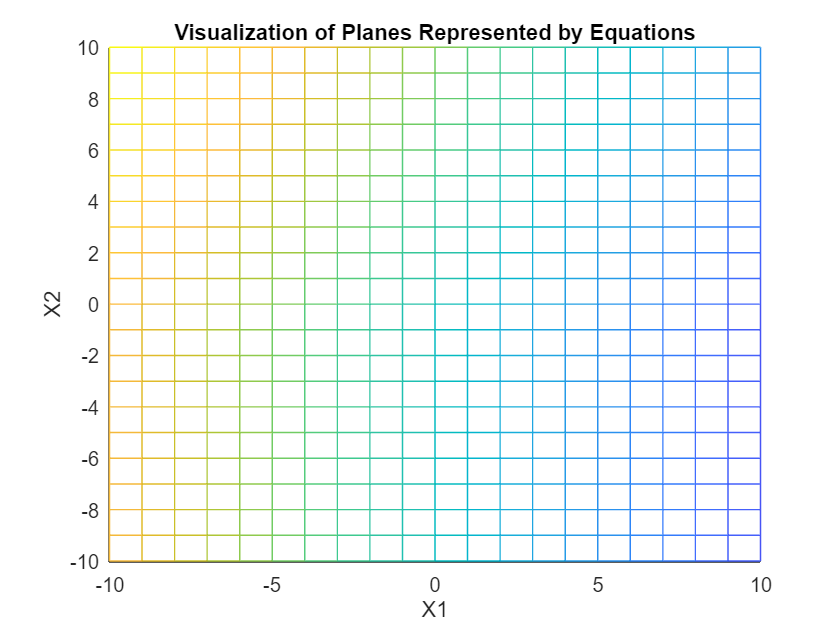

% Define the matrix A and vector b
A = [1 0 1; 1 -1 0; 2 -1 2];
b = [2; 3; 5];
% Create a new figure window for plotting
figure;

% Enable holding the plot, so multiple plots can be drawn on the same figure
hold on;

% Define a meshgrid for X1 and X2 values
[X1, X2] = meshgrid(-10:10);

% Loop through the 1st and 3rd rows of matrix A
for i = [1 3]
    % Calculate X3 values using the equation X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3)
    % This represents the plane for the equation given by the ith row of A and b
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3);
    
    % Plot the plane in 3D space using the mesh function
    mesh(X1, X2, X3);
end

% Label the axes for clarity
xlabel('X1');
ylabel('X2');
zlabel('X3');

% Provide a title for the plot
title('Visualization of Planes Represented by Equations');

% Display the grid lines
grid on;


rank_A = rank(A);
augmented_matrix = [A, b];
rank_augmented = rank(augmented_matrix);

fprintf('Linear System Solution:\n');

Linear System Solution:


fprintf('-----------------------\n\n');

-----------------------




fprintf('Coefficient Matrix (A):\n');

Coefficient Matrix (A):


disp(A);

     1     0     1
     1    -1     0
     2    -1     2




fprintf('\nRight-hand Side Vector (b):\n');


Right-hand Side Vector (b):


disp(b);

     2
     3
     5




fprintf('Gaussian Elimination Matrix (A):\n');

Gaussian Elimination Matrix (A):


disp(rref(augmented_matrix))

     1     0     0     2
     0     1     0    -1
     0     0     1     0




fprintf('\nSolution (x):\n');


Solution (x):


disp(linsolve(A,b));

     2
    -1
     0



### No Solution

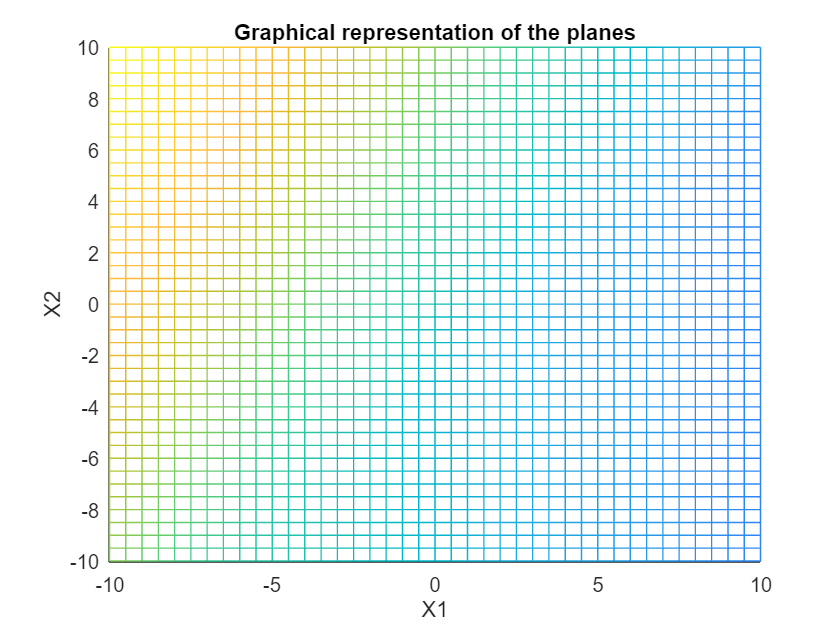

% Define the coefficient matrix A and the right-hand side vector b
A = [1 0 1; 1 -1 0; 2 -1 1];
b = [2; 7; 5];

% Create a figure for plotting
[X1, X2] = meshgrid(-10:0.5:10, -10:0.5:10);  % Define the range for X1 and X2
figure;
hold on;

% Plot each plane
for i = [1, 3]
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3);
    mesh(X1, X2, X3);
end
title('Graphical representation of the planes');
xlabel('X1');
ylabel('X2');
zlabel('X3');
hold off;


% Check if determinant is zero
if det(A) == 0
    disp('The determinant is zero. The matrix A is singular.');
else
    disp('The determinant is non-zero.');
end

The determinant is zero. The matrix A is singular.



% Try solving the system using linsolve
solution = linsolve(A, b);


% Check if the solution contains Inf or -Inf values
if any(isinf(solution))
    disp('The system does not have a solution.');
else
    disp('The system has a solution:');
    disp(solution)
end

The system does not have a solution.


## Systems of Equations and Least Squares Solution

In linear algebra, we often encounter systems of linear equations in the form 


$$Ax=b$$


where 

- A is a matrix

- x is a column vector of unknows

- b is a given column vector

There are instances where a system of equations has no exact solutions, especially if A is a non square matrix. In such a case, instead of finding an exact solution, we aim to find an approximate solution that minimizes that error

The error is defined as 


$$e=Ax-b$$


For a least squares solution, our goal is to find an *x* that minimizes the Euclidean norm of this error. 

### What is the Euclidean Norm?

The Euclidean norm is the distance between points, essentially an extension of the Pythagorean theorem into n-dimensional space. It is sometimes termed as the "magnitude" or "length" of the vector.


$$|v||_2 = \sqrt{v^2_1+v^2_2+...+v^2_n}$$


The least squared solution, denoted as *x*∗, minimizes the squared Euclidean norm of the error.


$$||Ax^*-b||_2^2$$


One way to find this solution is by using the pseudo-inverse of *A*, denoted $A^+$


$$x = A^+b$$


### Pseudo-Inverse

If m>n (tall matrix) 


$$x = (A^TA)^{-1}A^Tb$$


if m<n (fat matrix)


$$x = (A^T)(AA^T)^{-1}b$$


% Clear console and close any open figures
clc; close all;

% Define matrix A and compute its transpose
A = [0 4; 3 1; 3 -2];
A_transpose = A';

% Compute the product of A_transpose and A
C = A_transpose * A;

% Check if C is invertible and compute its inverse if so
if det(C) ~= 0
    C_inv = inv(C);
else
    disp('Matrix C is singular and cannot be inverted.');
end

% Work with an example matrix and compute the least squares solution
A_example = [1 -1; 0 1; 1 0];
b = [-3; -2; 1];
x_star = pinv(A_example) * b;

% Calculate the error associated with the computed solution
error_star = A_example * x_star - b;

% Compute the norm of the error
error_norm = norm(error_star);

% Display the results
disp('Least squares solution, x_star:');

Least squares solution, x_star:


disp(x_star);

   -1.0000
   -0.0000



disp('Norm of the error:');

Norm of the error:


disp(error_norm);

    3.4641




% Check error norms for random solutions
X = randn(2, 10);
for i = 1:10
    fprintf('Error norm for random solution %d: %f\n', i, norm(A * X(:, i) - b));
end

Error norm for random solution 1: 6.634800
Error norm for random solution 2: 12.287378
Error norm for random solution 3: 1.566425
Error norm for random solution 4: 6.143727
Error norm for random solution 5: 2.287985
Error norm for random solution 6: 4.249015
Error norm for random solution 7: 16.236643
Error norm for random solution 8: 3.243356
Error norm for random solution 9: 4.255916
Error norm for random solution 10: 8.236492


## Linear Algebra Notes: Handling Infinite Solutions with the Pseudo-Inverse

**Context:**

When dealing with linear systems of equations, we often seek unique solutions. However, there are instances where the system might have either no solution or an infinite number of solutions. The latter case, referred to as an *indeterminate system*, poses a challenge: how do we represent a solution when there are infinitely many possibilities?

**Objective:**

To find a meaningful representation for the solution of an indeterminate linear system.

% Clear console
clc;

% Define matrix A and vector b
A = [1 1];
b = 1;

% Compute the least squares solution using pseudo-inverse
x_star = pinv(A) * b;

% Compute the error for the solution
error_star = A * x_star - b;

% Display the results
disp('Least squares solution (x_star):');

Least squares solution (x_star):


disp(x_star);

    0.5000
    0.5000



disp('Error using x_star:');

Error using x_star:


disp(error_star);

  -2.2204e-16



fprintf('Norm of the error: %f\n', norm(error_star));

Norm of the error: 0.000000


**Results and Interpretation:**

- `x_star`: This is the best-fit solution in the least squares sense. It represents a solution that minimizes the overall error when used to approximate the system.

- `error_star`: Represents the error when using `x_star` as the solution.

- The `norm` function calculates the magnitude of the error vector. In this case, it returns a value of zero, indicating a perfect fit.

**Key Insights:**

- Using the pseudo-inverse, we can handle systems with infinite solutions by obtaining a representative solution that has the minimum error.

- For the given system, even though there are infinitely many solutions, the error associated with our representative solution (obtained using the pseudo-inverse) is zero.

- This approach allows us to gain meaningful insights and obtain a workable solution from a system that is otherwise indeterminate.

**Conclusion:**

While linear systems with infinite solutions might initially seem problematic, tools like the pseudo-inverse in linear algebra provide powerful ways to navigate such challenges. By focusing on error minimization, we can obtain representative solutions that, while not unique, are highly informative and useful.

## Visualizing Infinite Solutions in 3D Space

**Context:**

In linear algebra, systems of equations can be visualized as geometrical planes in space. When these planes intersect at a single point, it represents a unique solution. However, sometimes planes can overlap completely (coincide) or be parallel, leading to either infinite solutions or no solution, respectively.

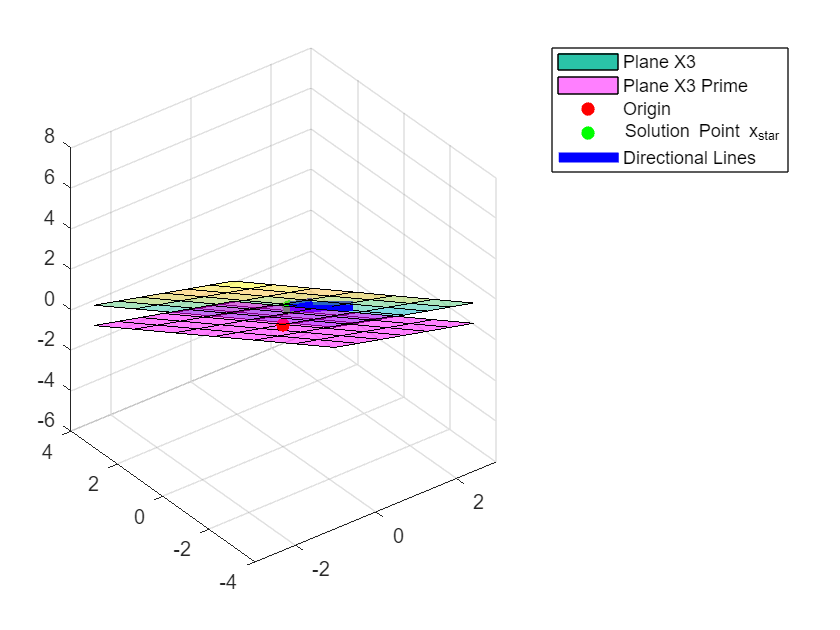

% Define matrix A, vector b, and calculate the symbolic pseudo-inverse solution
A = [1 1 1; 2 2 2; -3 -3 -3];
b = [1; 2; -3];
x_star = pinv(sym(A)) * b;

% Create meshgrid for visualization
[X1, X2] = meshgrid(-3:3);
X3 = 1 - X1 - X2;
X3_prime = - X1 - X2;

% Plot the surfaces and solution point
figure;
surf1 = surf(X1, X2, X3, 'FaceAlpha', 0.5);
hold on;
surf2 = surf(X1, X2, X3_prime, 'FaceColor', 'magenta', 'FaceAlpha', 0.5);
originPoint = plot3(0, 0, 0, '.r', 'MarkerSize', 20);
if exist('x_star', 'var')
    solutionPoint = plot3(x_star(1), x_star(2), x_star(3), '.g', 'MarkerSize', 20);
end
z1 = [1; -1; 0];
z2 = [0; -1; 1];
dirLine1 = plot3(x_star(1) + [0 z1(1)], x_star(2) + [0 z1(2)], x_star(3) + [0 z1(3)], 'b', 'linewidth', 5);
dirLine2 = plot3(x_star(1) + [0 z2(1)], x_star(2) + [0 z2(2)], x_star(3) + [0 z2(3)], 'b', 'linewidth', 5);

% Adding legend
legend([surf1, surf2, originPoint, solutionPoint, dirLine1], ...
    'Plane X3', 'Plane X3 Prime', 'Origin', 'Solution Point x_star', 'Directional Lines');

**Results and Interpretation:**

- 3D Visualization: The code plots two surfaces (`X3` and `X3_prime`) that are determined by the equations of the system. These surfaces represent the solution space.

- Red Point: This is the origin in the 3D space.

- Green Point (`x_star`): Represents the solution found using the pseudo-inverse. Given that our matrix has linearly dependent rows, the system has infinite solutions, and `x_star` is just one of those many solutions.

- Blue Lines: Emanating from the green point, these lines represent the directions of vectors `z1` and `z2` which are arbitrarily chosen here. They showcase that there are multiple directions (hence solutions) possible from the chosen point `x_star`.

**Key Insights:**

- The overlap of the surfaces in the visualization indicates that the system has an infinite number of solutions.

- The pseudo-inverse offers a way to find a representative solution (`x_star` in green) amidst this infinity.

- This visual approach helps to comprehend the geometric nature of linear systems and their solutions.

**Conclusion:**

Visualizing linear systems in 3D space provides an intuitive grasp of their solution structure. Even for systems with infinite solutions, computational tools like the pseudo-inverse enable us to derive meaningful representations. Such visual insights are invaluable in understanding the nuances of linear algebraic systems.

## EigenValues and EigenVectors

## Matrix Transformation Visualized

## Introduction

When we talk about matrices in the context of linear algebra and engineering, we're not just discussing arrays of numbers. Each matrix encapsulates a specific transformation. Imagine you're standing at a certain point in space. A matrix can stretch, rotate, reflect, or shear that point (and indeed, the entire space around it) into a new configuration.

## The Code: A Visual Demonstration

Let's take a look at our earlier MATLAB code to visualize these transformations.

- **Reflection over the Horizontal Axis**:The matrix `[1 0; 0 -1]` reflects a point over the horizontal axis. If our point was `(x, y)`, after the transformation, it becomes `(x, -y)`.

- **Reflection over the Vertical Axis**:The matrix `[-1 0; 0 1]` reflects a point over the vertical axis. The point `(x, y)` turns into `(-x, y)`.

- **Reflection over the Origin**:The matrix `[-1 0; 0 -1]` reflects a point over the origin, changing `(x, y)` into `(-x, -y)`.

- **Scaling by 3: **The matrix [ 3 0 ; 0 3] scales the x and y vector by 3, changing (x,y) into (3x,3y)

- **Rotation by 30deg: **The matrix [cos(pi/6), -sin(pi/6); sin(pi/6) cos(pi/6)] rotates every vector by 30 deg. 

By plotting these transformations, you visually see how each matrix changes the position of the points.

clc; clear all;

% Generate random points for all three transformations
x1 = 3*rand(1, 1000)-2;
x2 = rand(1, 1000);
X = [x1; x2];

% Transformation matrices
A1 = [1 0; 0 -1];     % Reflection over the X-axis
A2 = [-1 0; 0 1];    % Reflection over the Y-axis
A3 = [-1 0; 0 -1];   % Reflection over the Origin
A4 = [3 0; 0 3]

A4 =      3     0
     0     3


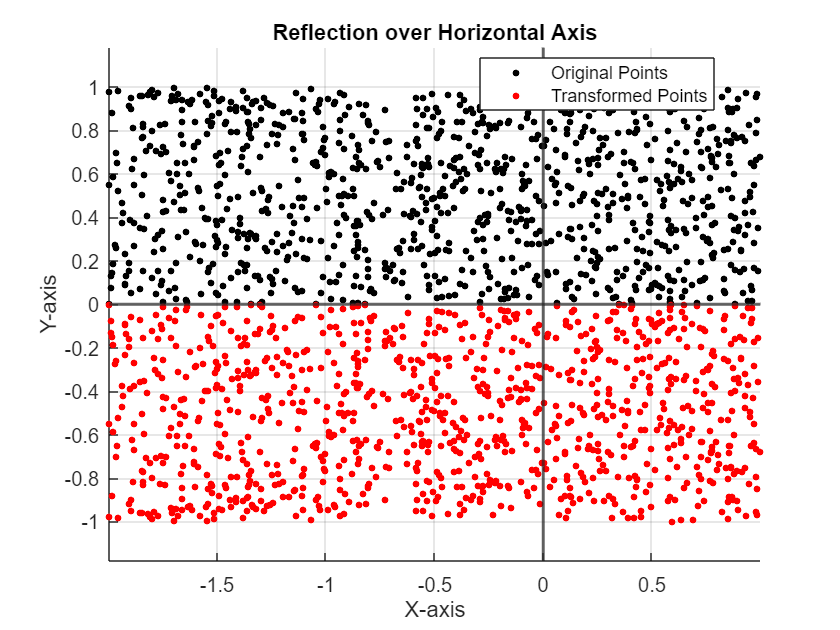

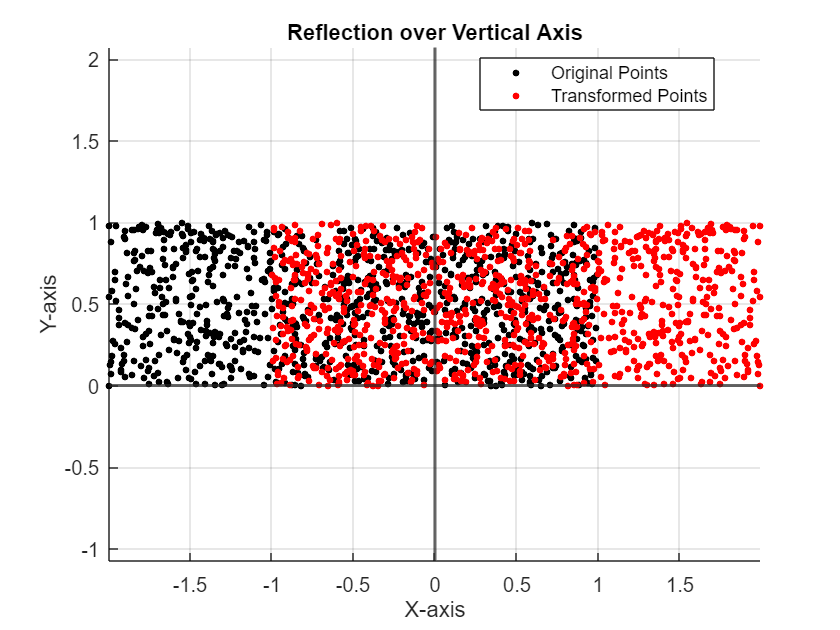

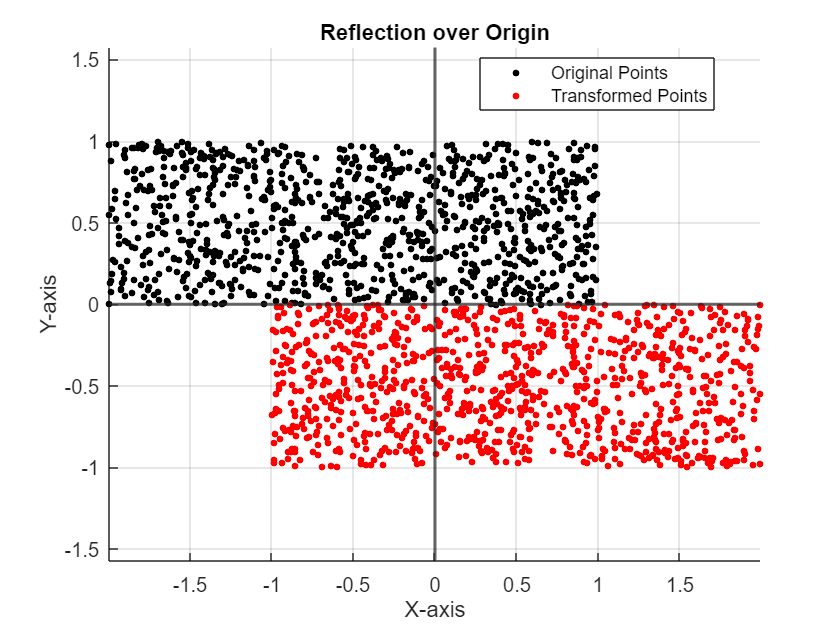

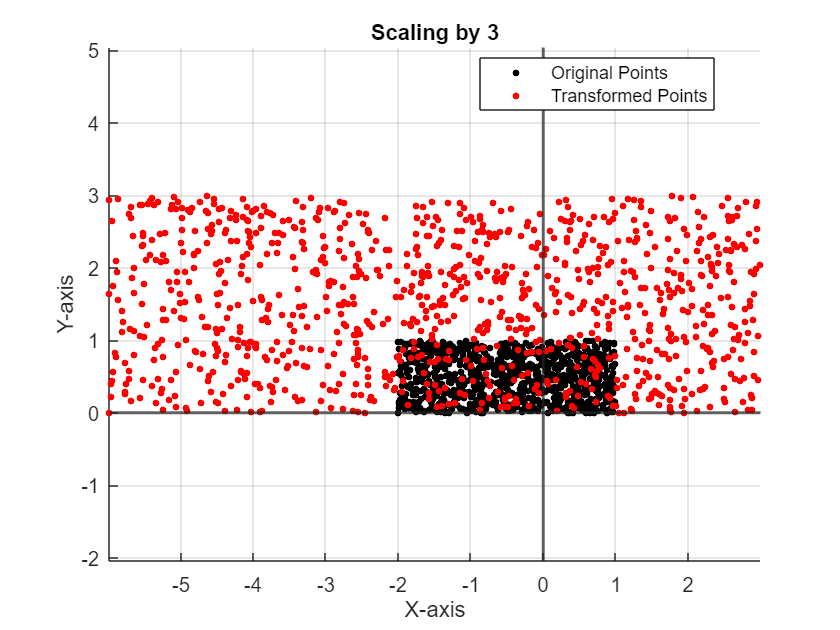




% Compute transformations
Y1 = A1 * X;
Y2 = A2 * X;
Y3 = A3 * X;
Y4 = A4 *X;

% Titles for the transformations
titles = {'Reflection over Horizontal Axis', 'Reflection over Vertical Axis', 'Reflection over Origin',"Scaling by 3"};

% Transformed data for the transformations
transformedData = {Y1, Y2, Y3,Y4};

% Plot
for i = 1:4
    figure, hold on, axis equal
    title(titles{i})
    plot(X(1, :), X(2, :), '.k', 'MarkerSize', 10)
    plot(transformedData{i}(1, :), transformedData{i}(2, :), '.r', 'MarkerSize', 10)
    xline(0, 'LineWidth', 1.5); yline(0, 'LineWidth', 1.5);
    legend('Original Points', 'Transformed Points', 'Location', 'best')
    xlabel('X-axis')
    ylabel('Y-axis')
    grid on
end

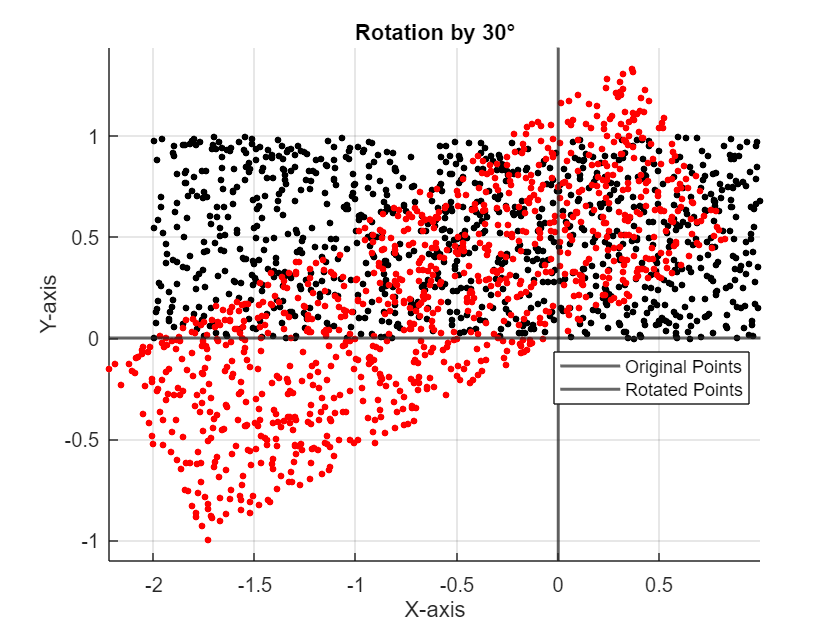


% Define the rotation matrix
theta = pi/6;  % 30 degrees in radians
A5 = [cos(theta), -sin(theta); sin(theta) cos(theta)];

% Apply the rotation to the points
Y5 = A5 * X;

% Plot the original and transformed points
figure;
hold on;
axis equal;
xline(0, 'LineWidth', 1.5);
yline(0, 'LineWidth', 1.5);
title('Rotation by 30°');
plot(X(1, :), X(2, :), '.k', 'MarkerSize', 10);
plot(Y5(1, :), Y5(2, :), '.r', 'MarkerSize', 10);

% Add labels and legend
xlabel('X-axis');
ylabel('Y-axis');
legend('Original Points', 'Rotated Points', 'Location', 'best');
grid on;

## Engineering Perspective

In engineering, these transformations are crucial. For instance:

- In graphics and gaming, matrices are used to transform 3D models into different perspectives on a 2D screen.

- In robotics, matrices help in calculating the transformations from one coordinate system to another, especially when figuring out how different parts of a robot move relative to each other.

- In signal processing, transformations like the Fourier transform (which can be thought of in terms of matrices) convert signals from the time domain to the frequency domain

## Eigenvalues and Eigenvectors

Diving deeper into the realm of matrices, there are some fascinating concepts that appear. One of the most crucial ones, especially in engineering and physics, is the idea of **eigenvalues** and **eigenvectors**

## **What are they?**

At its core, when we multiply a vector by a matrix, we transform that vector. Most vectors will change direction when they undergo this transformation. However, certain special vectors won't change their direction, they might only get stretched or shrunk. These vectors are called eigenvectors of the matrix. The factor by which they get stretched or shrunk is called an eigenvalue.

Mathematically, for a matrix *A* and a vector *v*, if *A*×*v*=*λ*×*v*, then *v* is an eigenvector and *λ* is its corresponding eigenvalue.

### Why Should We Care?

Eigenvectors and eigenvalues are fundamental in numerous applications:

- Stability Analysis: In systems theory, eigenvalues determine the stability of a system.

- Modal Analysis: In structural engineering, eigenvectors represent modes of oscillation.

- Principal Component Analysis: In data science, the method uses eigenvectors to reduce dimensions.

- Quantum Mechanics: Quantum states are often eigenvectors of certain operators.

% Clear workspace, command window, and close all figures
clear all;
clc;
close all;

% Generate random points
x1 = 3*rand(1, 1000) - 2;
x2 = rand(1, 1000);
X = [x1; x2];

% Define matrix A for linear transformation
A = [1 2; 3 4];
Y = A * X;

% Plot the transformed points
figure;
hold on;
axis equal;
plot(Y(1, :), Y(2, :), '.b', 'MarkerSize', 10);

% Calculate eigenvalues using symbolic math toolbox
syms lambda;
eigenvalueEquation = det(A - lambda * eye(2))

$$eigenvalueEquation = \lambda^{2}-5\,\lambda -2$$

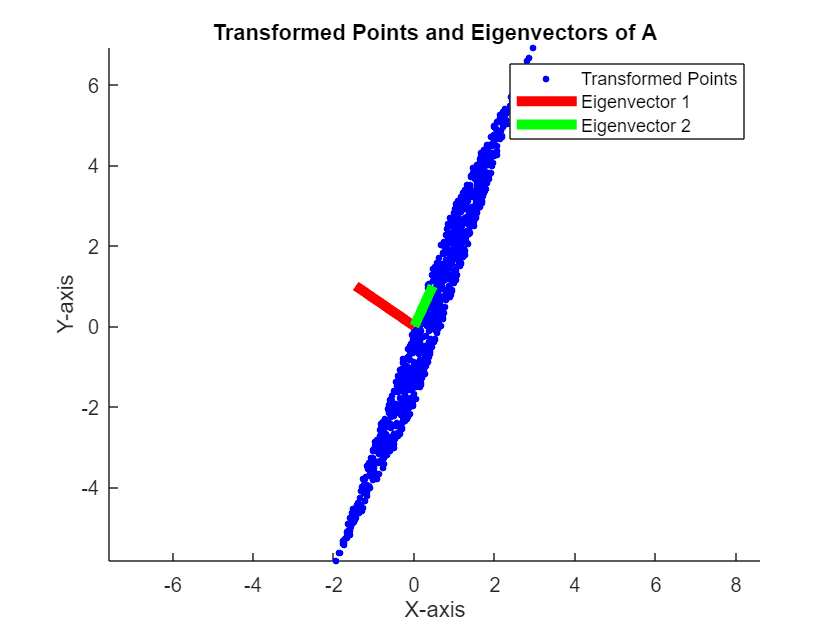

sol = solve(eigenvalueEquation == 0);

% Calculate eigenvectors associated with each eigenvalue
v1 = null(A - sol(1) * eye(2));
v2 = null(A - sol(2) * eye(2));

% Plot the eigenvectors
plot([0 v1(1)], [0 v1(2)], 'r', 'linewidth', 5);
plot([0 v2(1)], [0 v2(2)], 'g', 'linewidth', 5);

% Provide context
title('Transformed Points and Eigenvectors of A');
xlabel('X-axis');
ylabel('Y-axis');
legend('Transformed Points', 'Eigenvector 1', 'Eigenvector 2');


% Display eigenvalues
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(sol);

$$\left(\begin{array}{c} \frac{5}{2}-\frac{\sqrt{33}}{2}\\ \frac{\sqrt{33}}{2}+\frac{5}{2} \end{array}\right)$$

### Code Breakdown

- Defined a matrix `A`.

- Transformed our points `X` using `A` to get `Y`.

- Sought eigenvalues using the determinant of `(A - lambda*I)`, where `I` is the identity matrix.

- Once we have the eigenvalues (`sol`), we found the eigenvectors (`v1` and `v2`).

In the plot, you'll see the transformed points, but more importantly, you'll also see the eigenvectors of the matrix. These eigenvectors give a clear geometric intuition: while all other vectors change direction when transformed by `A`, these specific vectors (eigenvectors) retain their direction and only get stretched or shrunk.